### Labo B: Analyse van digitale filters

#### Eerste orde IIR filter

IIR filter met volgende vergelijking: $y(n) = x(n) + a_{1}y(n-1)$

a1 = [0.1 0.9 1 1.1];
x = ones([1, 10]);

Teken de topologie:

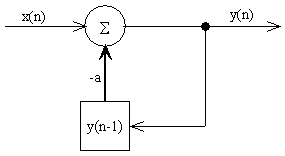

Wegens terugkoppeling is dit een IIR netwerk.

Als we manueel de eerste 4 samples van y(n) berekenen:

for n = 1:length(a1)
    y(n, 1) = x(1) + a1(n) * 0;
    for i = 2:length(x)
        y(n, i) = x(i) + a1(n) * y(i-1);
    end
end
y

y = 	1.0e+42 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   

Voor de limietwaarden is deze:

for i = 1:length(a1)
    lim(i) = 1/ (1 - a1(i));
end
lim

lim =     1.1111   10.0000       Inf  -10.0000


De stapresponsie van een eerste orde analoog laagdoorlaat filter:

De stapresponsie van een digitaal ldl filter:

Laten we dit nu implementeren in Matlab en analyseren:

Geef x = 200 samples van waarde 1, filter en bewijs bovenstaande nummers.

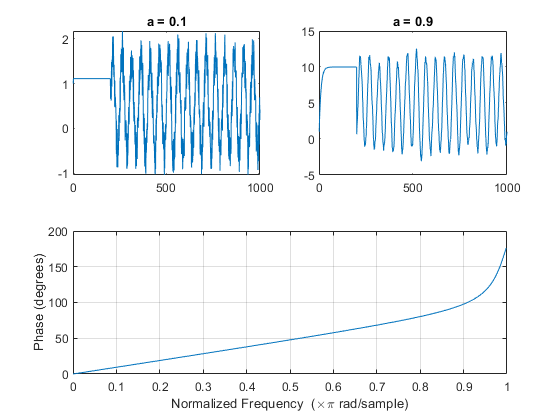

x = ones([1, 200]);
for n = 1:length(a1)
    y(n, 1) = x(1) + a1(n) * 0;
    for i = 2:length(x)
        y(n, i) = x(i) + a1(n) * y(n, i-1);
    end
end
subplot(2, 2, 1);
plot(y(1, :))
title('a = 0.1');
subplot(2, 2, 2);
plot(y(2, :))
title('a = 0.9');

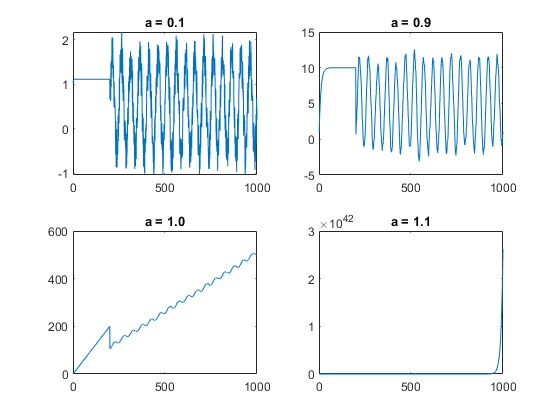

subplot(2, 2, 3);
plot(y(3, :))
title('a = 1.0');
subplot(2, 2, 4);
plot(y(4, :))
title('a = 1.1');

Pas nu je signaal aan, en sample volgende golfvorm met een frequentiefs= 1000 Hz tussen t= 0 sent= 1 s:

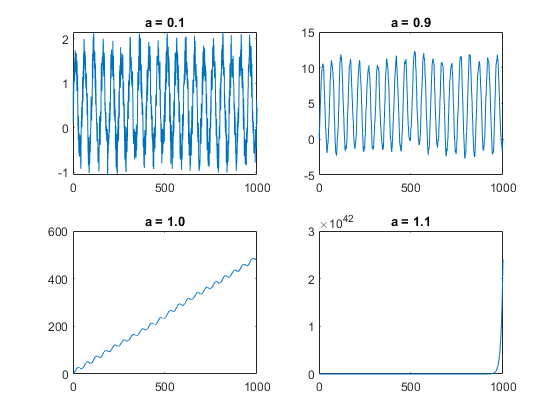

figure;
fs = 1000;
Ts = 1/fs;
p = 20;
n = rand([1, 1001]);
t = (0:Ts:1);
x = sin(2 * pi * p * t) + n;
for n = 1:length(a1)
    y(n, 1) = x(1) + a1(n) * 0;
    for i = 2:length(x)
        y(n, i) = x(i) + a1(n) * y(n, i-1);
    end
end
subplot(2, 2, 1);
plot(y(1, :))
title('a = 0.1');
subplot(2, 2, 2);
plot(y(2, :))
title('a = 0.9');
subplot(2, 2, 3);
plot(y(3, :))
title('a = 1.0');
subplot(2, 2, 4);
plot(y(4, :))
title('a = 1.1');

figure;

We zien duidelijk dat hoe hoger we a1 hebben, hoe minder hoge frequenties voorkomen in het signaal.

De Z-transformatie is: $H(z) = \frac{z}{z - a_{1}}$

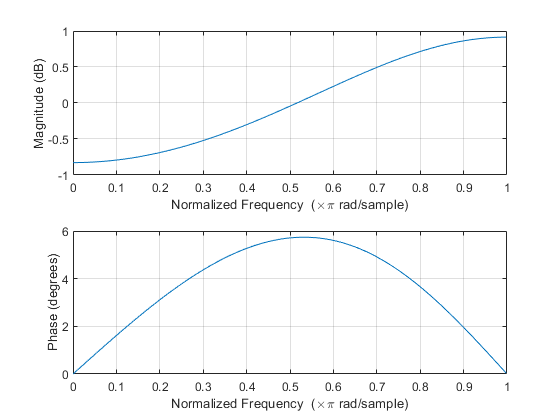

freqz([1], [1,a1(1)])

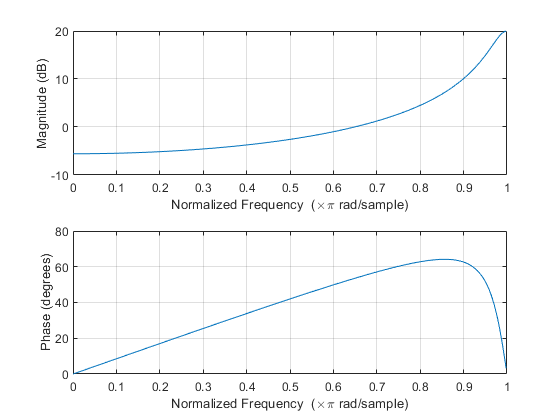

freqz([1], [1,a1(2)])

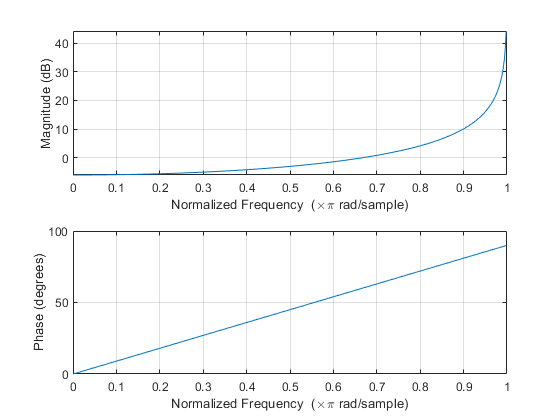

freqz([1], [1,a1(3)])

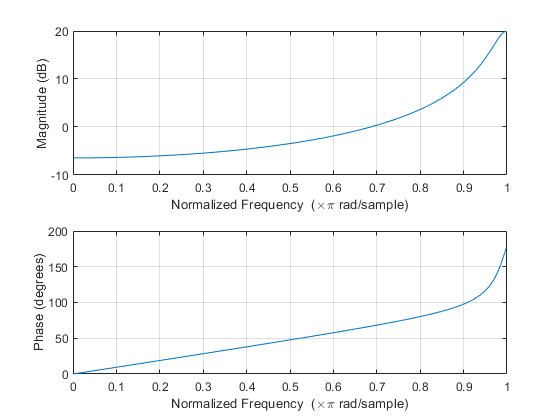

freqz([1], [1,a1(4)])

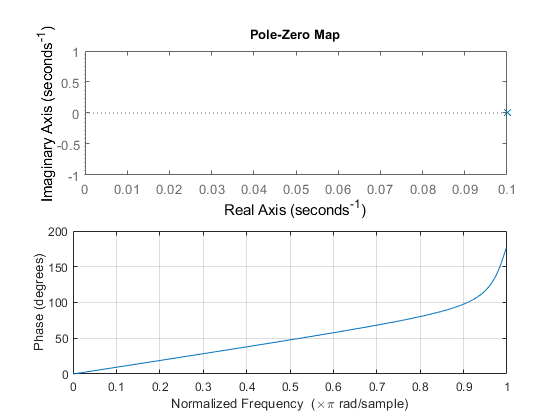

pzplot(tf([1], [1, -a1(1)]))